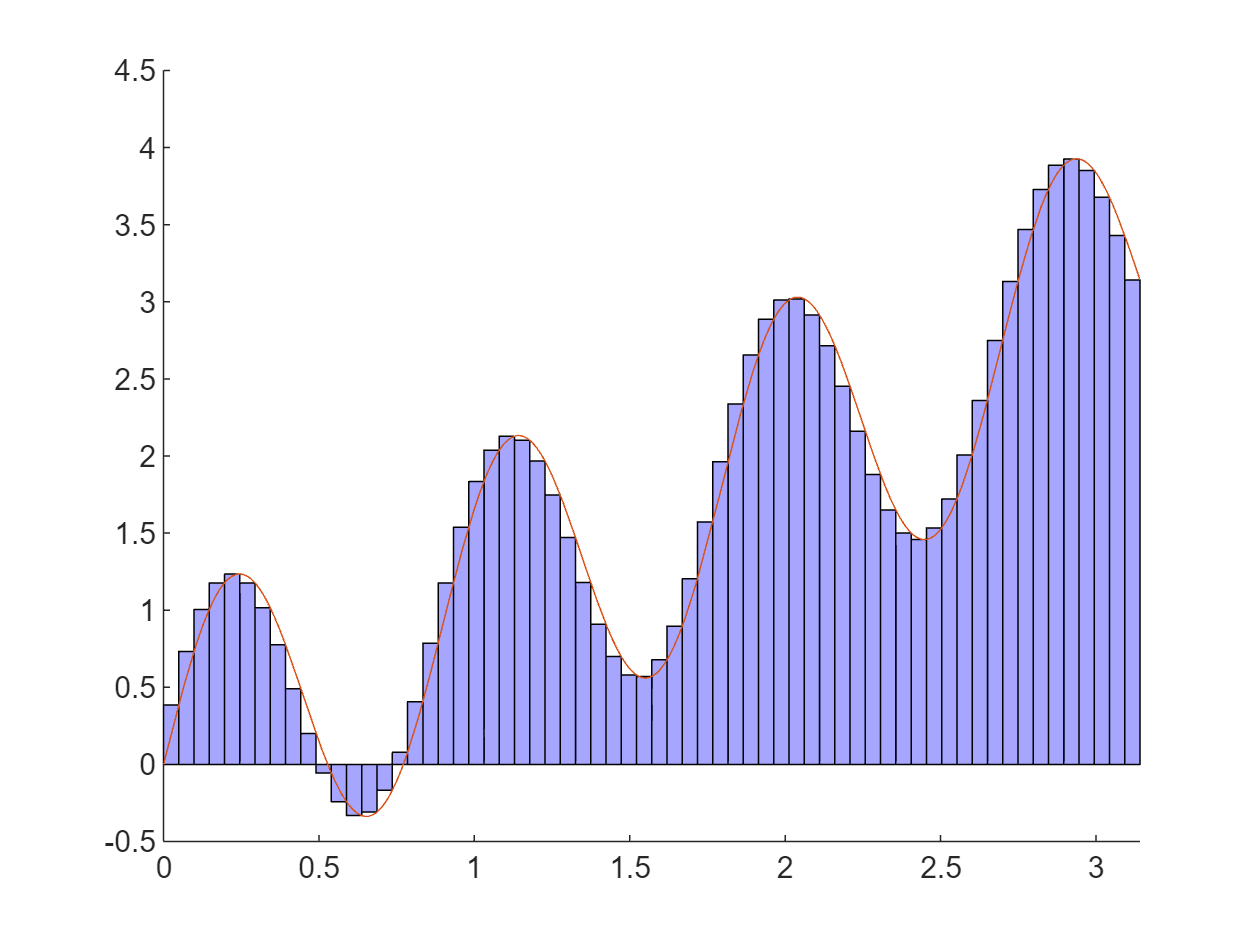

% 定义函数
f = @(x) sin(7*x)+x;

% 定义积分区间
a = 0;
b = pi;

% 定义n值
n_values = [2, 4, 8, 16, 32, 64];

% 初始化结果数组
right_rect_results = zeros(1, length(n_values));
trapz_results = zeros(1, length(n_values));
simpson_results = zeros(1, length(n_values));
warning('off','all')
% 对每个n值进行计算
for i = 1:length(n_values)
    n = n_values(i);
    h = (b - a) / n;
    X = linspace(b,a,n);
    
    % right rectangle
    right_rect_results(i) = h * sum(f(X(2:end)));
    hold off
    for k = 1:n
        plot(integralShape(@(x)x-x+f(a+k*h),a+(k-1)*h,a+k*h),'FaceColor','b')
        xlim([a,b])
        hold on        
    end
    fplot(f,[a,b])
    exportgraphics(gcf,'lab10.gif','Append',true);
end

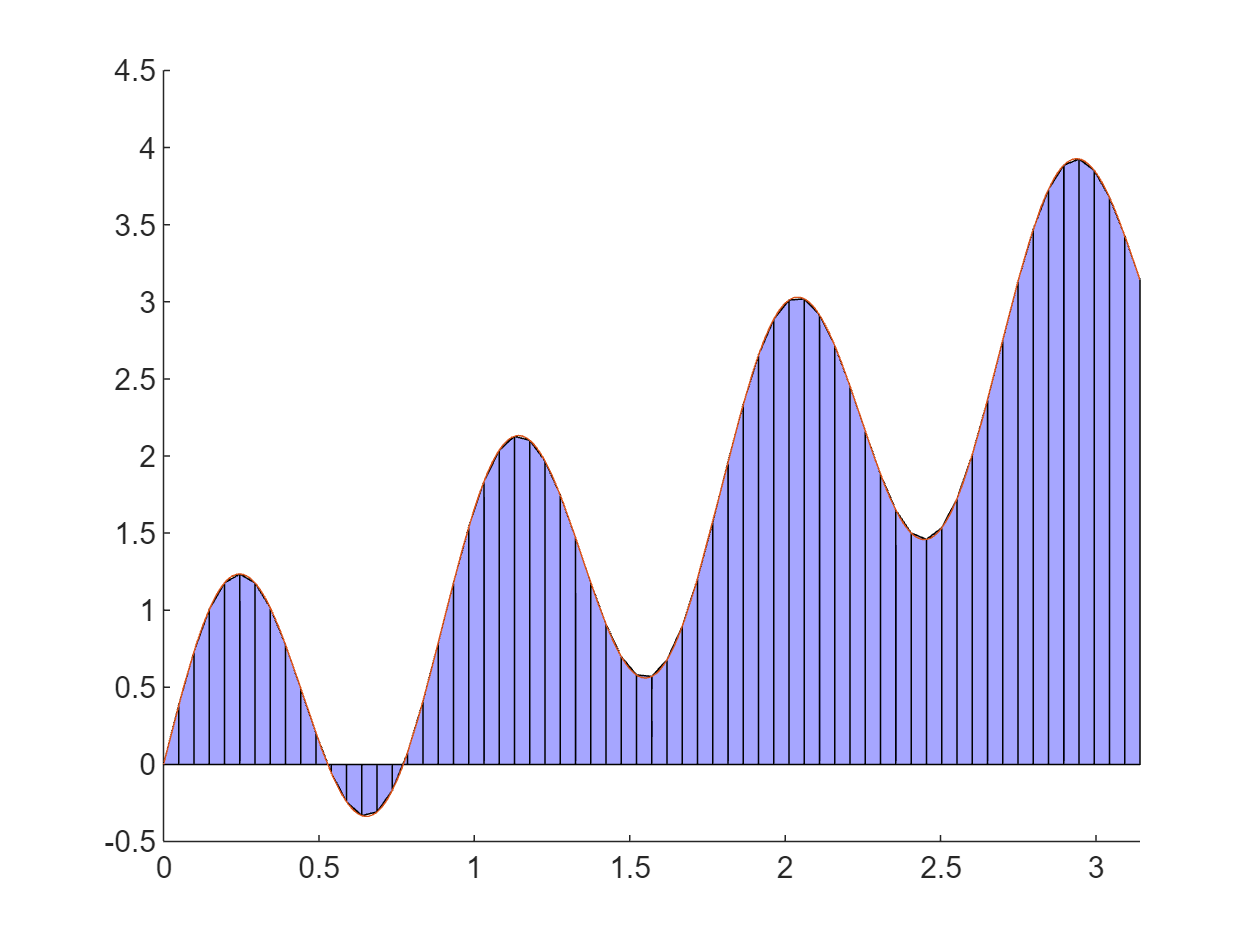

for i = 1:length(n_values)
    n = n_values(i);
    h = (b - a) / n;
    X = linspace(b,a,n);
    
    % right rectangle
    right_rect_results(i) = h * sum(f(X(2:end)));
    hold off
    for k = 1:n
        ak = a+(k-1)*h;
        bk = a+k*h;
        plot(integralShape(@(x)f(bk)+(f(bk)-f(ak))/h*(x-bk),ak,bk),'FaceColor','b')
        xlim([a,b])
        hold on        
    end
    fplot(f,[a,b])
    exportgraphics(gcf,'lab10.gif','Append',true);
end

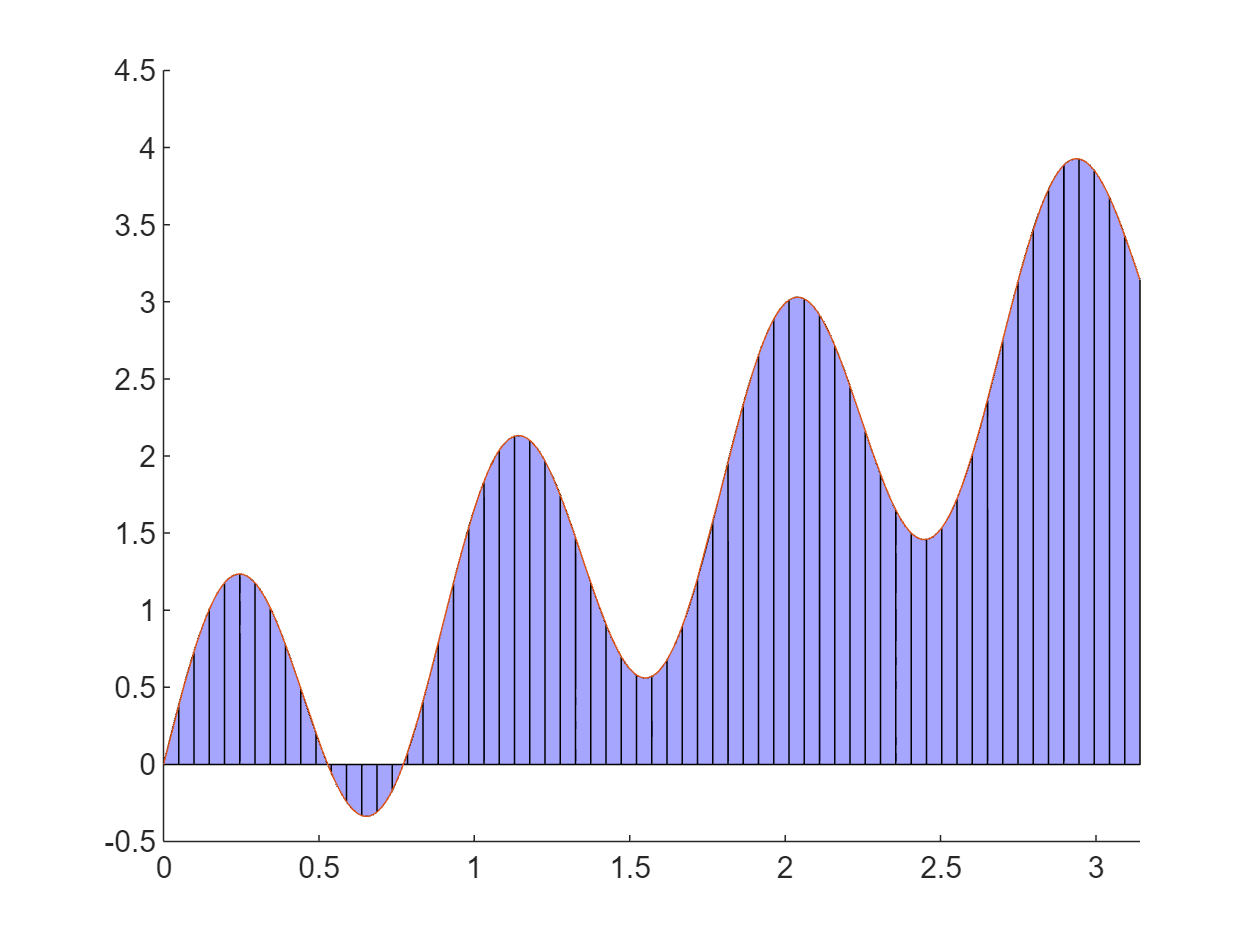

for i = 1:length(n_values)
    n = n_values(i);
    h = (b - a) / n;
    X = linspace(b,a,n);
    
    % right rectangle
    right_rect_results(i) = h * sum(f(X(2:end)));
    hold off
    for k = 1:n
        ak = a+(k-1)*h;
        bk = a+k*h;
        fpoly = polyfit([ak,bk,(ak+bk)/2],[f(ak),f(bk),f((ak+bk)/2)],2);
        plot(integralShape(@(x)polyval(fpoly,x),ak,bk),'FaceColor','b')
        xlim([a,b])
        hold on        
    end
    fplot(f,[a,b])
    exportgraphics(gcf,'lab10.gif','Append',true);
end

function pgon = integralShape(f,a,b)
X = linspace(a,b,100);
Y = f(X);
pgon = polyshape([X,X(end:-1:1)],[Y,zeros(1,100)]);
pgon = pgon.simplify;
end